#### 子文件夹路径

clear
cd("E:\MyProject\matlab\MATLAB Drive\Repository\DtN-FEM_SH\")
addpath("import\");
addpath("plot\");
addpath("SH\");
addpath("import\mesh\")

## 网格信息

fileName = 'E:\MyProject\matlab\MATLAB Drive\Repository\DtN-FEM_SH\import\mesh\pipe_depth\d0.2';
matName = [fileName ,'.mat'];
load(matName)

## 入射条件

incident = struct;
incident.mode = 1; % 入射模态
cutoff = [0.01, 1.5708, 3.1416, 4.7124, 6.2843, 7.85399]; % SH波截止频率(无量纲频率)
incident.w = cutoff(incident.mode):0.05:4.5; % 扫频采样点(无量纲频率)
% incident.w = linspace(cutoff(incident.mode),8,165);
incident.n = length(incident.w);

单频率测试

% incident.mode = 2;
% incident.w = 1.8;
% incident.n = 1;

## 扫频求解散射系数

cR = cell(incident.n,1);cT = cell(incident.n,1); eng = cell(incident.n,1);	kd = cell(incident.n,1); K = zeros(incident.n,1);

U_s_B = zeros(incident.n,length(n.bottom));
U_s_T = zeros(incident.n,length(n.top));

C = zeros(incident.n,1);

for it = 1:incident.n
	wd = incident.w(it);
	[cR{it}, cT{it}, U, eng, kd] = dtn_fem_sh(matName, wd, incident.mode);
	K(it) = kd(incident.mode);
	eng_tot(it) = eng.tot;
	U_s_B(it,:) = U.sc(n.bottom)'; % 位移
	U_s_T(it,:) = U.sc(n.top)';
	tmpC = cT{it};	C(it) = tmpC(incident.mode); % 反射系数
end

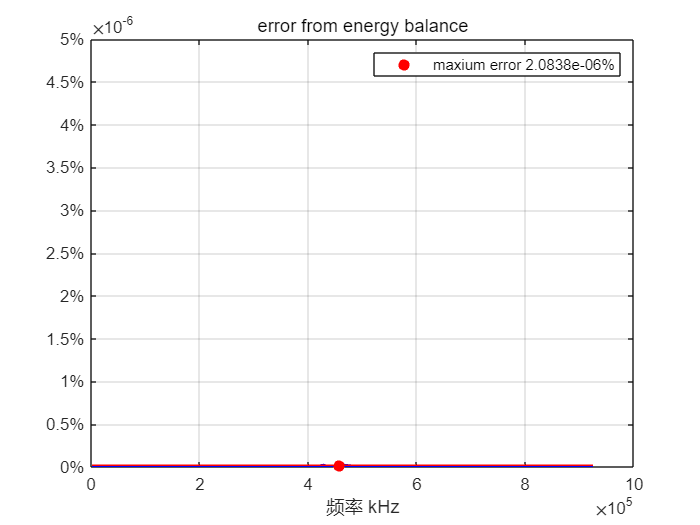

run draw_error.mlx

load train
sound(y)